#### Задача 3.7.

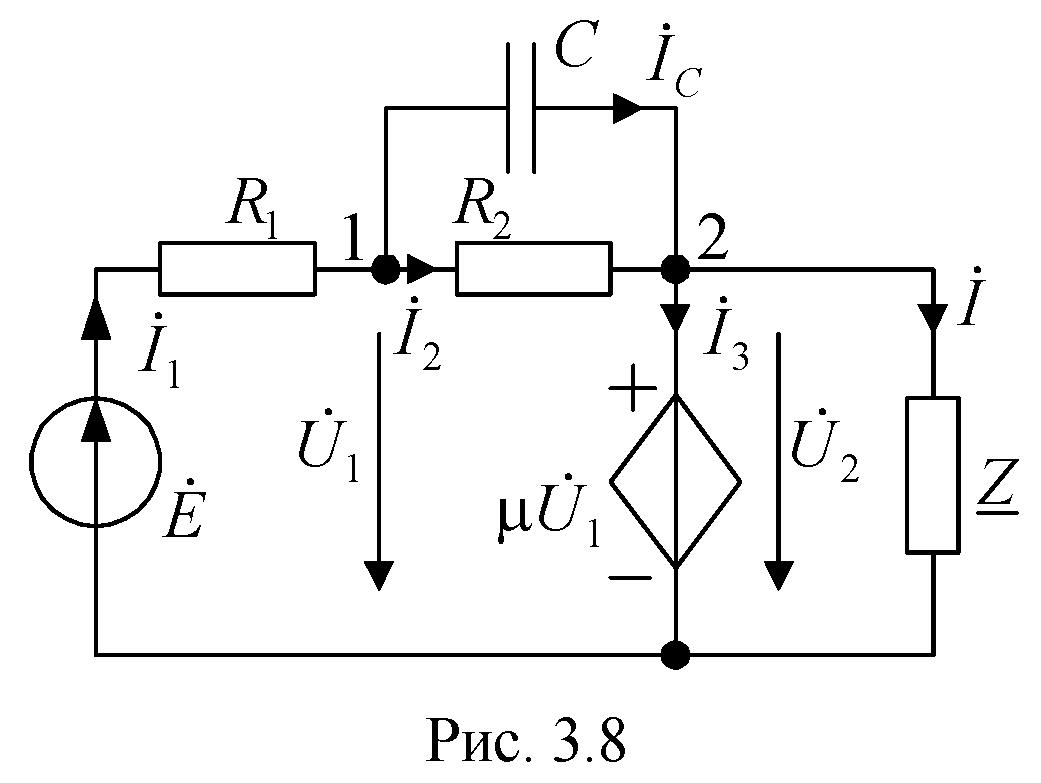

% Рис.3.8
clear
format short
digits(3)
E=2; % В
f=1000; % Гц
R1=1600; % Ом
R2=2700; % Ом
C_uz=0.05; % мкФ
mu=-1;
Z=5100+3000j; % Ом

syms R1 R2 Z_C U1 U2 E mu

Уравнения метода узловых напряжений

eq1=(1/R1+1/R2+1/Z_C)*U1-(1/R2+1/Z_C)*U2==E/R1,...
eq2=U2==mu*U1

$$eq1 = U_{1}\,\left(\frac{1}{R_{1}}+\frac{1}{R_{2}}+\frac{1}{Z_{C}}\right)-U_{2}\,\left(\frac{1}{R_{2}}+\frac{1}{Z_{C}}\right)=\frac{\text{E}}{R_{1}}$$

$$eq2 = U_{2}=U_{1}\,\mu$$

Решение уравнений

slv=solve(eq1,eq2,[U1 U2])

slv = struct with fields:
    U1: [1×1 sym]
    U2: [1×1 sym]


U1slv=slv.U1,...
U2slv=slv.U2

$$U1slv = \frac{\text{E}\,R_{2}\,Z_{C}}{R_{1}\,R_{2}+R_{1}\,Z_{C}+R_{2}\,Z_{C}-R_{1}\,R_{2}\,\mu -R_{1}\,Z_{C}\,\mu }$$

$$U2slv = \frac{\text{E}\,R_{2}\,Z_{C}\,\mu }{R_{1}\,R_{2}+R_{1}\,Z_{C}+R_{2}\,Z_{C}-R_{1}\,R_{2}\,\mu -R_{1}\,Z_{C}\,\mu }$$

Подставляем значения

omega=f*2*pi

omega = 6.2832e+03

C=C_uz*1e-6

C = 5.0000e-08

Z_C=vpa(-1j/(omega*C))

$$Z\_C = -3188.0\,\mathrm{i}$$

E=2; % В
R1=1600; % Ом
R2=2700; % Ом
mu=-1;
Z=5100+3000j; % Ом

Получаем U1 и U2

U1=vpa((E*R2*Z_C)/(R1*R2 + R1*Z_C + R2*Z_C - R1*R2*mu - R1*Z_C*mu)),...
Up1=vpa([abs(U1),angle(U1)*180/pi])   

$$U1 = 0.755-0.348\,\mathrm{i}$$

$$Up1 = \left(\begin{array}{cc} 0.831 & -24.7 \end{array}\right)$$

U2=mu*U1, Up2=vpa([abs(U2),angle(U2)*180/pi]) 

$$U2 = -0.755+0.348\,\mathrm{i}$$

$$Up2 = \left(\begin{array}{cc} 0.831 & 155.0 \end{array}\right)$$

Действующее значение тока нагрузки

I=U2/Z,  Ip=vpa([abs(I),angle(I)*180/pi]) 

$$I = -8.03e-5+1.15e-4\,\mathrm{i}$$

$$Ip = \left(\begin{array}{cc} 1.41e-4 & 125.0 \end{array}\right)$$

syms t
Im=sqrt(2)*I, Imp=vpa([abs(Im),angle(Im)*180/pi])

$$Im = \sqrt{2}\,\left(-8.03e-5+1.15e-4\,\mathrm{i}\right)$$

$$Imp = \left(\begin{array}{cc} 1.99e-4 & 125.0 \end{array}\right)$$

Мгновенное значение тока

i=Imp(1)*sin(omega*t+Imp(2)*pi/180)

$$i = 1.99e-4\,\sin\left(0.693\,\pi +2000\,\pi \,t\right)$$